clc; clear; close all;

g = 9.81;
zw = 0.8;
tw = 10;
nsh = 3;
ig = 46;
m = 9000;
mueq = 0.15;
dd = 0.45;
omega0 = 5;

t = 0:60;

zp = zw *sin((2*pi/tw)*t)

zp =          0    0.4702    0.7608    0.7608    0.4702    0.0000   -0.4702   -0.7608   -0.7608   -0.4702   -0.0000    0.4702    0.7608    0.7608    0.4702    0.0000   -0.4702   -0.7608   -0.7608   -0.4702   -0.0000


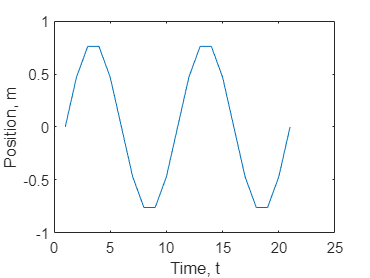

zpdot = diff(zp);
zpdotmax = max(zpdot); %m/s
zpdotdot = diff(zpdot);

plot(zp)
xlabel("Time, t")
ylabel("Position, m")

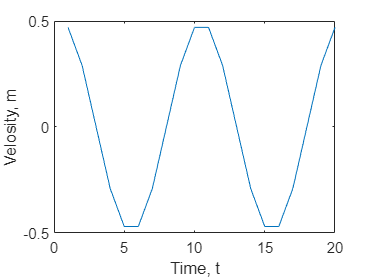

figure
plot(zpdot)
xlabel("Time, t")
ylabel("Velosity, m")

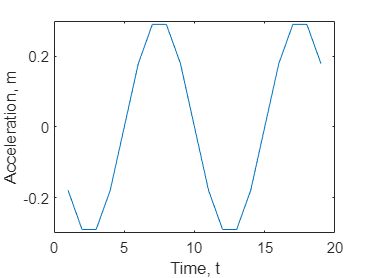


figure
plot(zpdotdot)
xlabel("Time, t")
ylabel("Acceleration, m")


omegad = zpdotmax/(dd/2)        %rad/s

omegad = 2.0899

omegam = omegad*ig*nsh          %rad/s

omegam = 288.4066

omegam2rpm = omegam*2*pi/180*60      % rpm

omegam2rpm = 604.0374




Mm = (m*g*dd)/(2*nsh*2*ig) * (1+(mueq * tanh(omegad/omega0)));
